# Eksempel 1

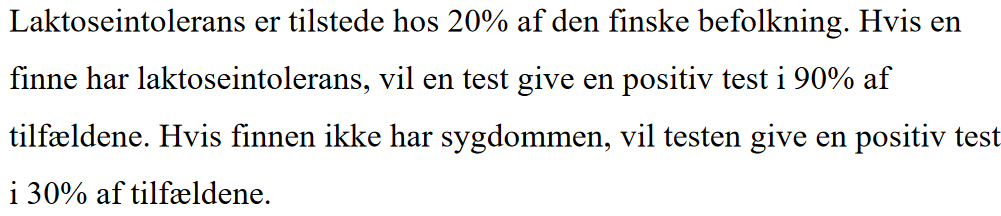

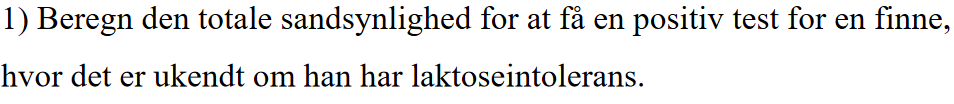

clearvars
% Event A - Er laktoseintolerant
Pr_A = 0.2;
% Event NA = NOT A - Er ikke laktoseintolerant
Pr_NA = 1 - Pr_A;
% Event B - Test er positiv - udregnes
% Pr( B | A ) = Sandsynlighed for positiv test, givet at man er laktoseintolerant
Pr_BA = 0.9;
% Pr( B | Not A ) = Sandsynlighed for positiv test, givet at man ikke er laktoseintolerant
Pr_BNA = 0.3;
Pr_B = (Pr_A * Pr_BA) + (Pr_NA * Pr_BNA)

Pr_B = 0.4200

% Pr( A | B ) - Sandsynligheden for at man er syg, givet at testen er positiv
% Bayes formel
% P( A | B ) = ( Pr( B | A ) * Pr(A) ) / Pr(A)
Pr_AB = (Pr_BA * Pr_A)/Pr_B

Pr_AB = 0.4286

# Eksempel 2

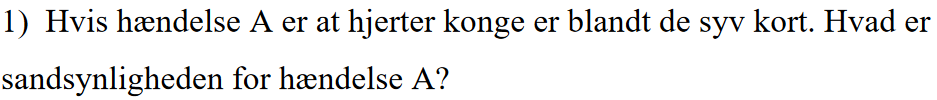

% format rat = skriv i brøker
% format short = default
clearvars
format rat
% Ud af 52 kort er 1 af dem kongen.
% Sandsynlighed for at trække kongen = 1/52;
Pr_Konge = 1/52;
% Man trækker 7 kort
Pr_A = 7*Pr_Konge

Pr_A =        7/52    


format short
Pr_SparEs = 1/52;
Pr_B = 7*Pr_SparEs;
% Multiplikationsreglen
% Pr(A ^ B) = Pr( A | B ) * Pr(B)
% Pr(A | B) = Sandsynlighed for kongen er i de 7 kort, givet at esset er der.
% Hvis esset er der, er der kun 6 ud af de 7 kort der kan være kongen
% Der er desuden et kort mindre, da vi nu ved at esset ikke er i dækket. Altså er Pr_Konge = 1/51
Pr_Konge = 1/51;
Pr_AB = 6 * Pr_Konge;
Pr_A_AND_B = Pr_AB * Pr_B

Pr_A_AND_B = 0.0158

% For uafhænighed gælder 
% Pr(A|B) = Pr(A)
% Pr(AB) =  Pr(A)*Pr(B)
Pr_AB == Pr_A

ans = logical
   0


Pr_A_AND_B == (Pr_A)*(Pr_B)

ans = logical
   0


% Begge er logisk 0 = false, altså er de ikke uafhængige

% Formel = 

format long
% 52 kort, 7 kort trækkes
% (n, r) = (52, 7)
n = 52; r = 7;
n_fac = factorial(n); r_fac = factorial(r);
kombinationer = n_fac / ( factorial(n-r) * r_fac )

kombinationer =    133784560


# Eksempel 3

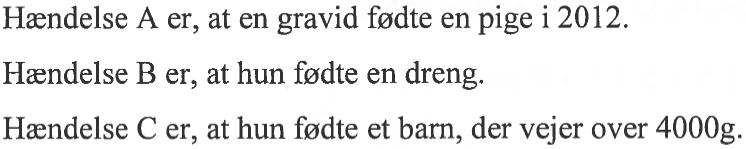

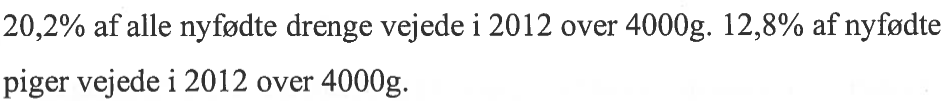

clearvars
format short
n_drenge = 29785; n_piger = 28131; total = n_drenge + n_piger;
Pr_A = n_piger / total

Pr_A = 0.4857

% Formel for total sandsynlighed
% Pr(A) = sum af Pr(A|B) * Pr(B)
% I dette tilfælde:
% Pr(C) = Pr(C|A)*Pr(A) + Pr(C|B)*Pr(B)
Pr_B = 1 - Pr_A;
Pr_CA = 0.128; Pr_CB = 0.202;
Pr_C = (Pr_CA*Pr_A) + (Pr_CB * Pr_B)

Pr_C = 0.1661

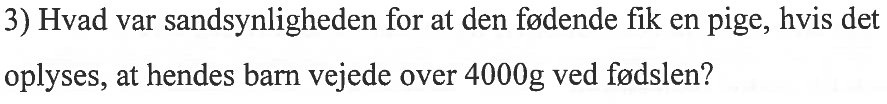

% Pr(A | C)
Pr_AC = ( Pr_CA * Pr_A) / Pr_C

Pr_AC = 0.3744

# Eksempel 4

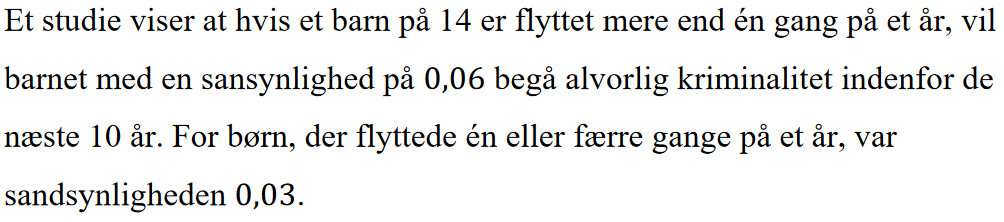

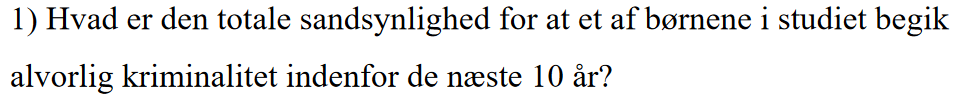

clearvars
% Pr(A) = Flyttet mere end 1 gang
% Pr(B) = Begår kriminalitet
% Pr(B | A) = Chance for at man begår kriminalitet, givet at man er flyttet mere end 1 gang
Pr_BA = 0.06;
% Pr(B | Not A) = Chance for at man begår kriminalitet, givet man er flyttet 1 eller færre gange
Pr_B_NotA = 0.03;
Pr_B = Pr_BA*0.31 + Pr_B_NotA*(1-0.31)

Pr_B = 0.0393

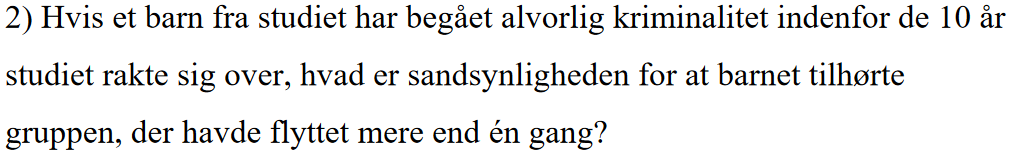

% Pr(A | B) = Chancen for at have flyttet mere end 1 gang, givet at man har begået kriminalitet
% Bayes Formel
Pr_AB = (Pr_BA * 0.31) / Pr_B

Pr_AB = 0.4733

# Eksempel 5

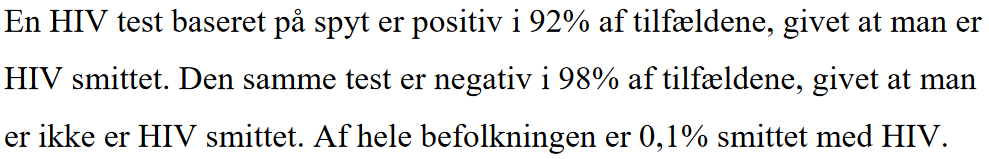

clearvars
format short
% Pr(A) = HIV Smittet
Pr_A = 0.001; Pr_NotA = 1 - Pr_A;
% Pr(B) = Positiv Test
% Pr(B|A) = Positiv test givet at man er smittet
Pr_BA = 0.92;
% Pr(B|Not A) = Positiv test givet man ikke er smittet
Pr_B_NotA = 1-0.98;
% Pr(B and A) = Pr(B|A) * Pr(A)
Pr_A_and_B = Pr_BA * Pr_A

Pr_A_and_B = 9.2000e-04

Pr_B = (Pr_B_NotA * Pr_NotA) + Pr_A_and_B

Pr_B = 0.0209

% Pr(A | B) = Sandsynlighed for at være smittet, givet testen er positiv
% Betinget sandsynlighed
Pr_AB = (Pr_A_and_B)/Pr_B

Pr_AB = 0.0440

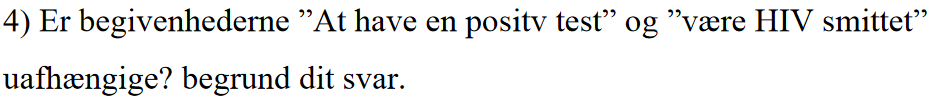

% For uafhængighed gælder
% Pr(A|B) = Pr(A)
% Pr(A and B) = Pr(A) * Pr(B)
Pr_AB == Pr_A

ans = logical
   0


Pr_A_and_B == Pr_A * Pr_B

ans = logical
   0


% Begge er logisk 0 (false), altså er de ikke uafhængige

# Eksempel 6

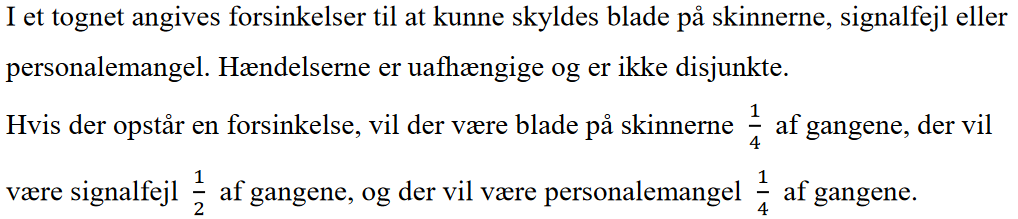

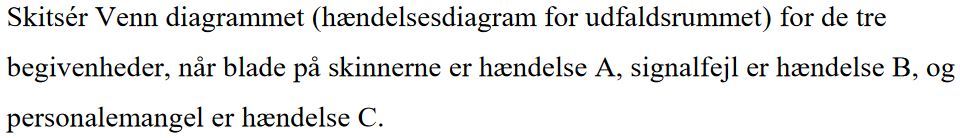

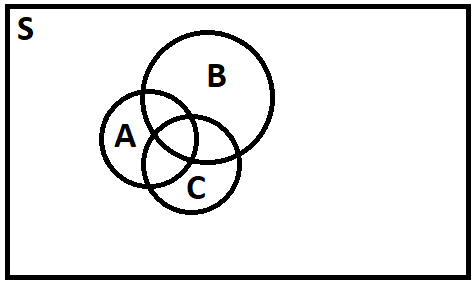

clearvars
% Alle tilfælde er uafhængige
% Pr(A and B) = P(A|B) * P(B)
% For uafhængige gælder:
% Pr(A|B) = Pr(A)
% Pr(A and B) = Pr(A) * Pr(B)
format rat
Pr_A = 0.25; Pr_B = 0.5; Pr_C = 0.25;
Pr_A_and_B = Pr_A * Pr_B

Pr_A_and_B =        1/8     


% Pr(A eller B) = Pr(A) + Pr(B) - Pr(A og B);
Pr_A_or_B = Pr_A + Pr_B - Pr_A_and_B

Pr_A_or_B =        5/8     


% Pr(A eller B eller C) = 
% Pr_A + Pr_B + Pr_C - Pr(A og B) - Pr( A og C) - Pr(B og C) + Pr(A og B og C)
Pr_A_or_B_or_C = Pr_A + Pr_B + Pr_C - (Pr_A*Pr_B) - (Pr_A * Pr_C) - (Pr_B * Pr_C) + (Pr_A*Pr_B*Pr_C)

Pr_A_or_B_or_C =       23/32    


# Eksempel 7

clearvars
format short
dage = 30;
svar = (0.2*dage/2) + (0.3*dage/2)

svar = 7.5000

% A = Sandsynlighedfor regn
% B = Sandsynlighed for at være i sidste halvdel
% P(A|B) = Sandsynlighed for regn, givet vi er i den sidste halvdel
P_B = 0.5;
P_NotB = P_B;
P_AB = 0.3;
P_A_NotB = 0.2;
P_A = (P_AB*P_B)+(P_A_NotB*P_NotB);
% P(B|A) Sandsynlighed for at være i den sidste halvdel, givet at det regner
% Bayes Formel
P_BA = (P_AB*P_B)/P_A

P_BA = 0.6000

% AAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAAA

# Eksempel 8

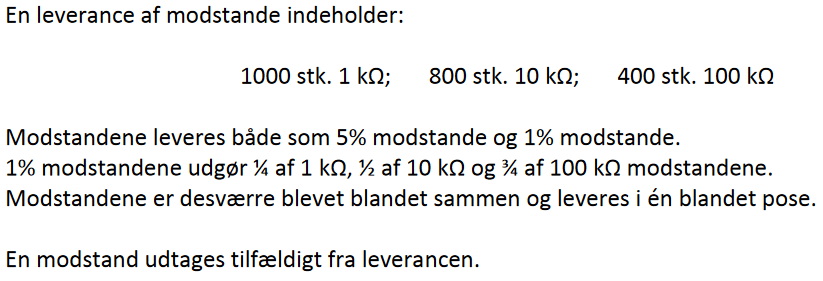

clearvars
n_1k = 1000; n_10k = 800; n_100k=400; total= n_1k + n_10k + n_100k;
P_A1 = n_1k/total; P_A10 = n_10k/total; P_A100 = n_100k/total;

% Multiplikationsregel
P_1p10k = 0.5*P_A10

P_1p10k =        2/11    


% Total sandsynlighed
% B1 = 1% modstand
P_B1 = (0.25*P_A1) + (0.5*P_A10) + (0.75*P_A100)

P_B1 =       19/44    


P_B5 = 1 - P_B1;
% Fra opgaven: P(B1% | A100k) = 0.75
P_B5_A100 = 1 - 0.75;
% P(A100|B5)
% Bayes Formel
P_A100_B5 = (P_B5_A100 * P_A100) / P_B5

P_A100_B5 =        2/25    


# Eksempel 9

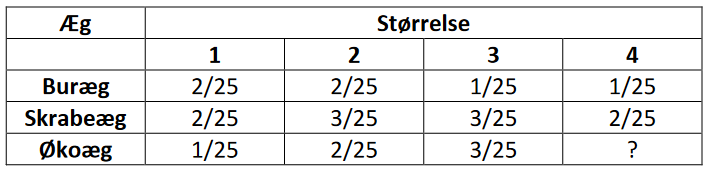

clearvars
format rat
% Total for alle skal være 1
svar = (25 - 6 - 10 - 6)/25

svar =        3/25    


svar = (1/25) + (3/25) + (3/25)

svar =        7/25    


svar = (2/25) + (2/25) + (1/25) + (1/25)

svar =        6/25    


% A = Æg er størrelse 2
% B = Æg er skrabeæg
P_A = (2/25) + (3/25) + (2/25);
P_B = (2/25) + (3/25) + (3/25) + (2/25);
% Find P(B|A)
% Betinget sandsynlighed
P_A_and_B = 3/25;
P_BA = P_A_and_B / P_A

P_BA =        3/7     
